Ece 341 lab #4

Q1

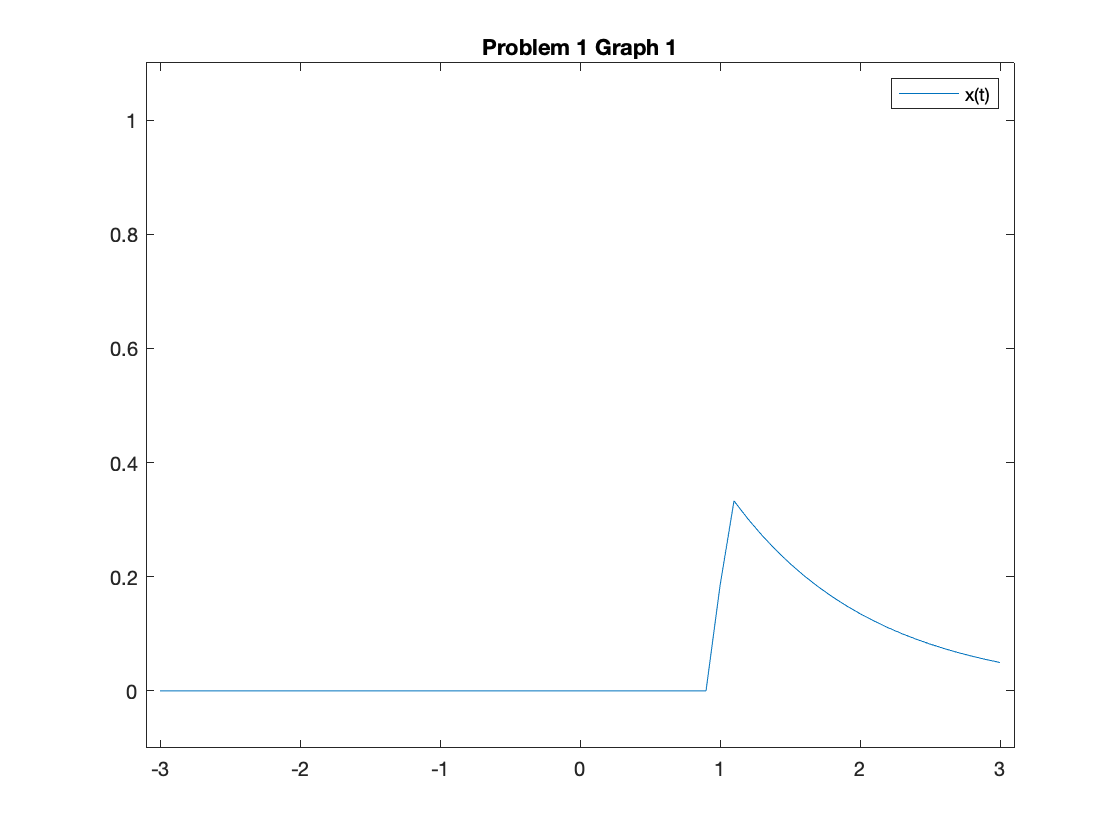

clear all
clc

t = -3:0.1:3;
x = exp((-t)) .* heaviside(t-1);
y1 = t .* exp(-t) .* heaviside(t);
y2 = t .* exp(-t) .* heaviside(t - 2);

plot(t,x)
legend('x(t)')
xlim([-3.1 3.1]);
ylim([-0.1 1.1]);
title('Problem 1 Graph 1')

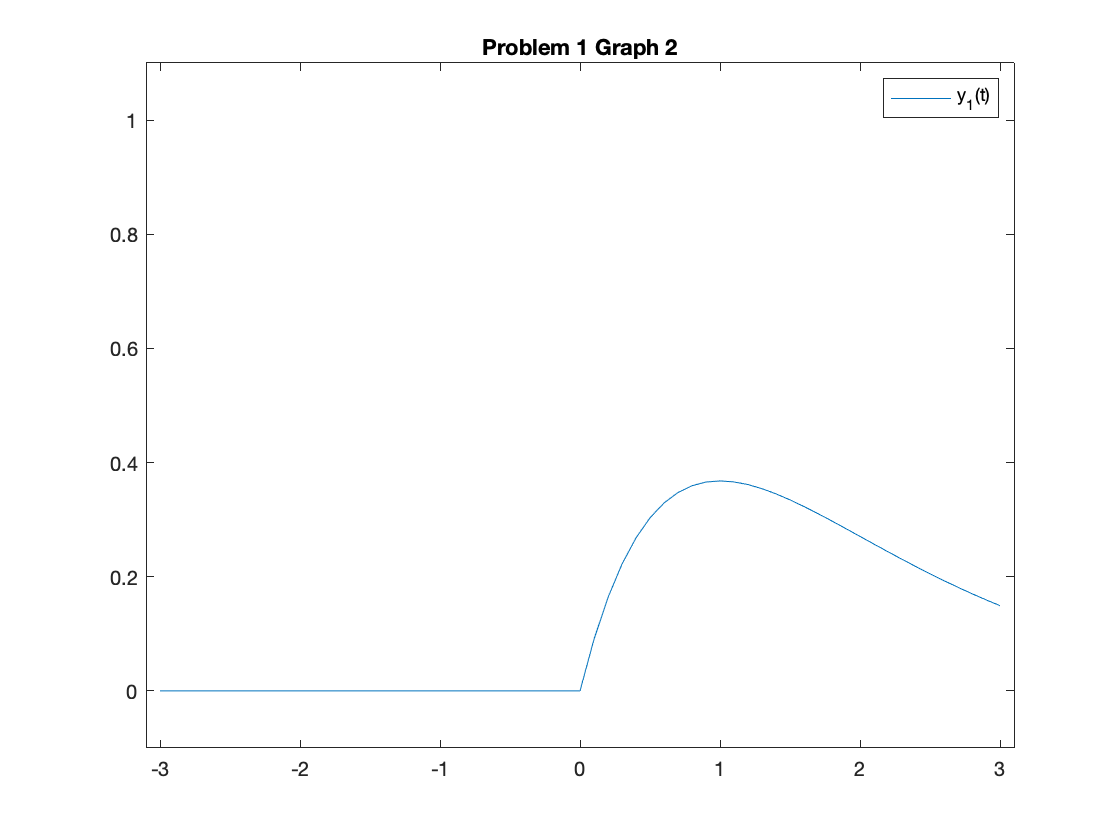


plot(t,y1)
legend('y_1(t)')
xlim([-3.1 3.1]);
ylim([-0.1 1.1]);
title('Problem 1 Graph 2')

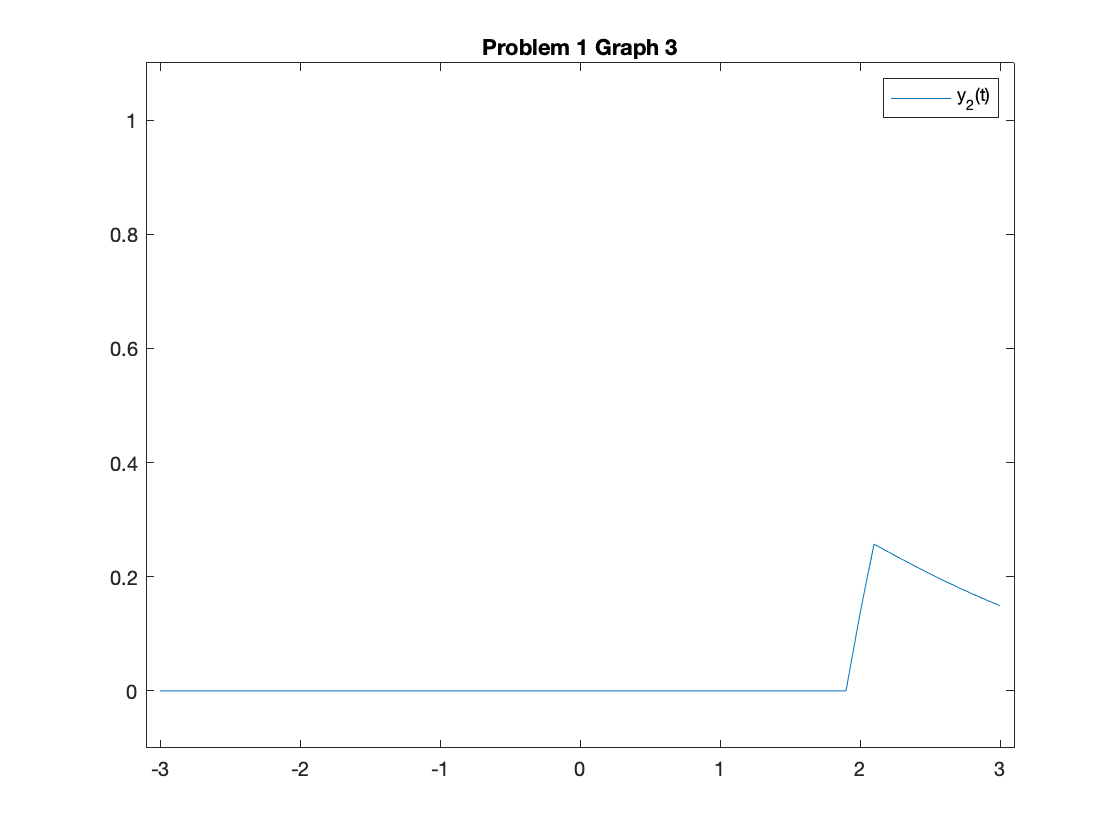


plot(t,y2)
legend('y_2(t)')
xlim([-3.1 3.1]);
ylim([-0.1 1.1]);
title('Problem 1 Graph 3')

Q3

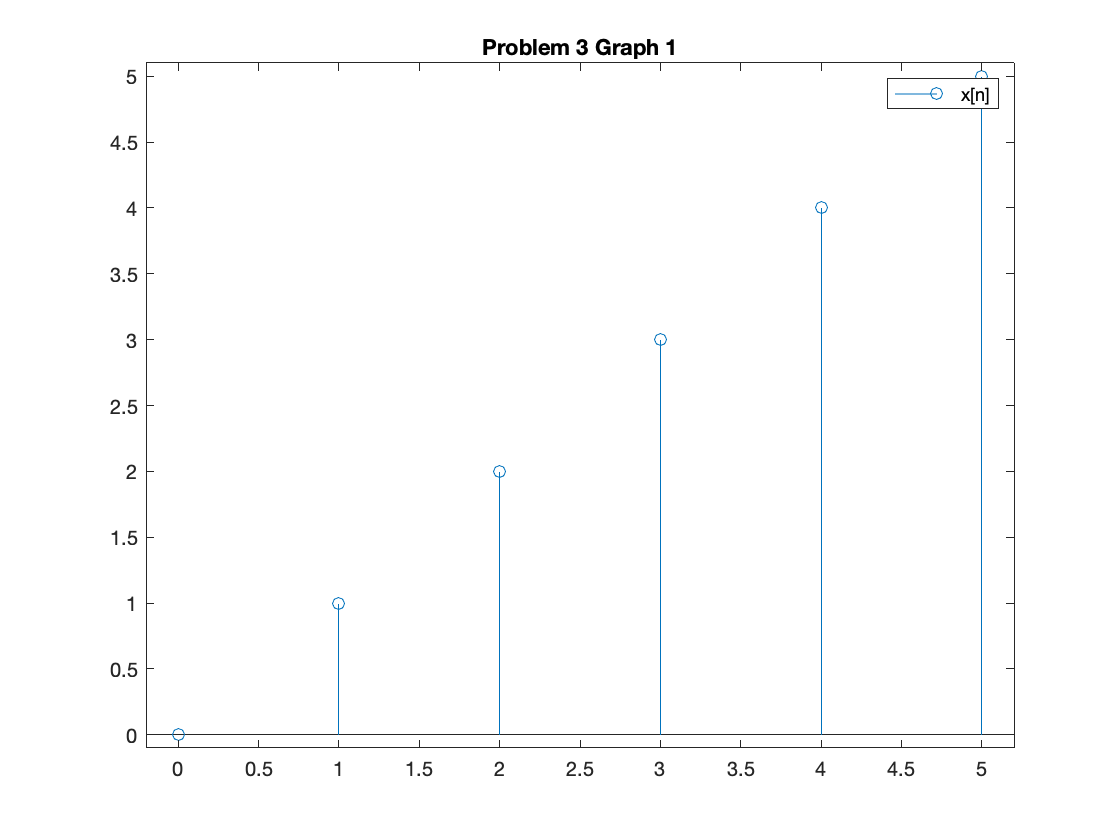

clear all
clc

n = 0:5;
x = 0:5;

stem(n,x);
axis([-0.2 5.2 -0.1 5.1]);
legend('x[n]')
title('Problem 3 Graph 1')

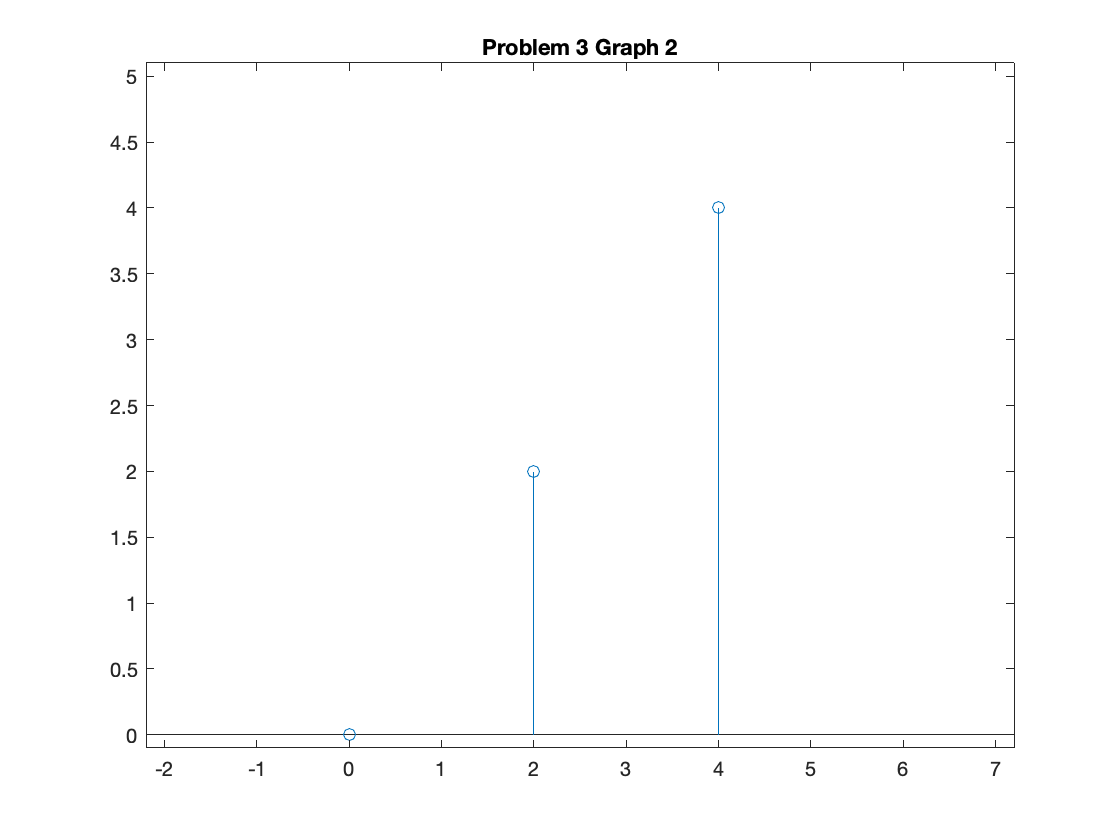


a = 2;
y = downsample(x,a);
stem(0:2:4, y)
axis([-2.2 7.2 -0.1 5.1]);
title('Problem 3 Graph 2')

Q4

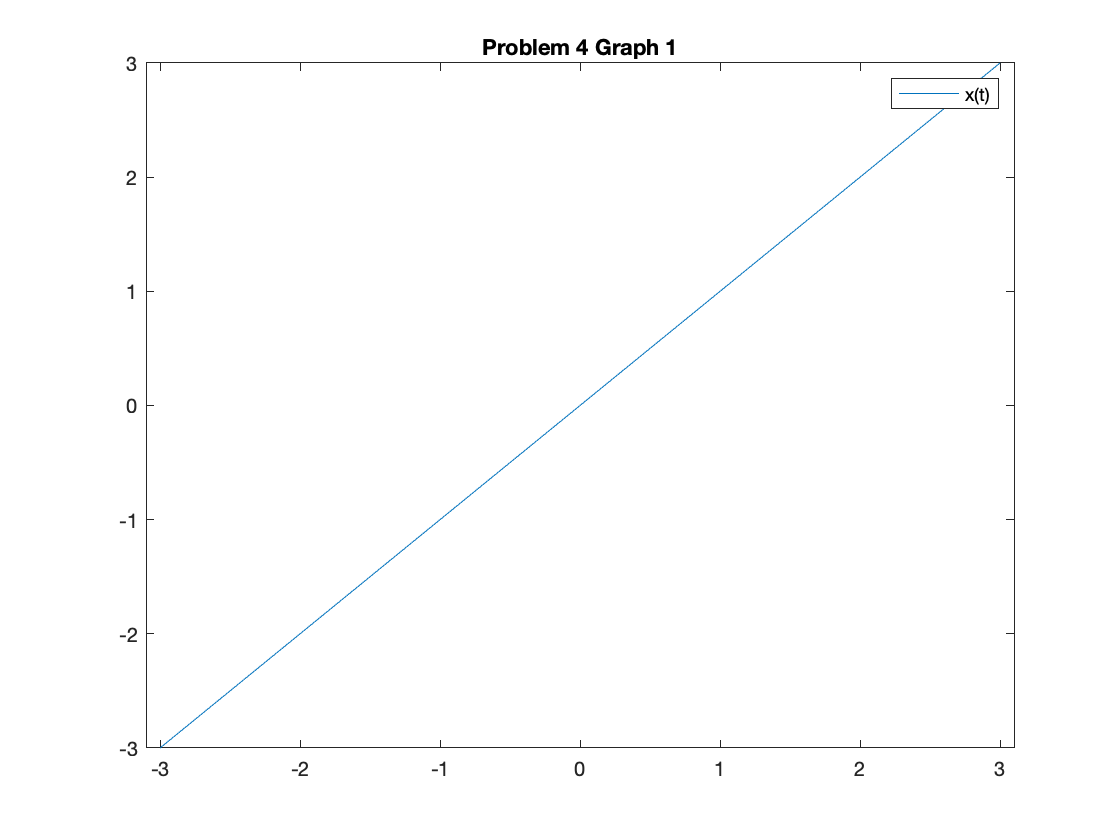

clear all
clc

t = -3:0.1:3;
x = -3:0.1:3;

y = cos(x);

plot(t,x);
legend('x(t)')
xlim([-3.1 3.1]);
title('Problem 4 Graph 1')

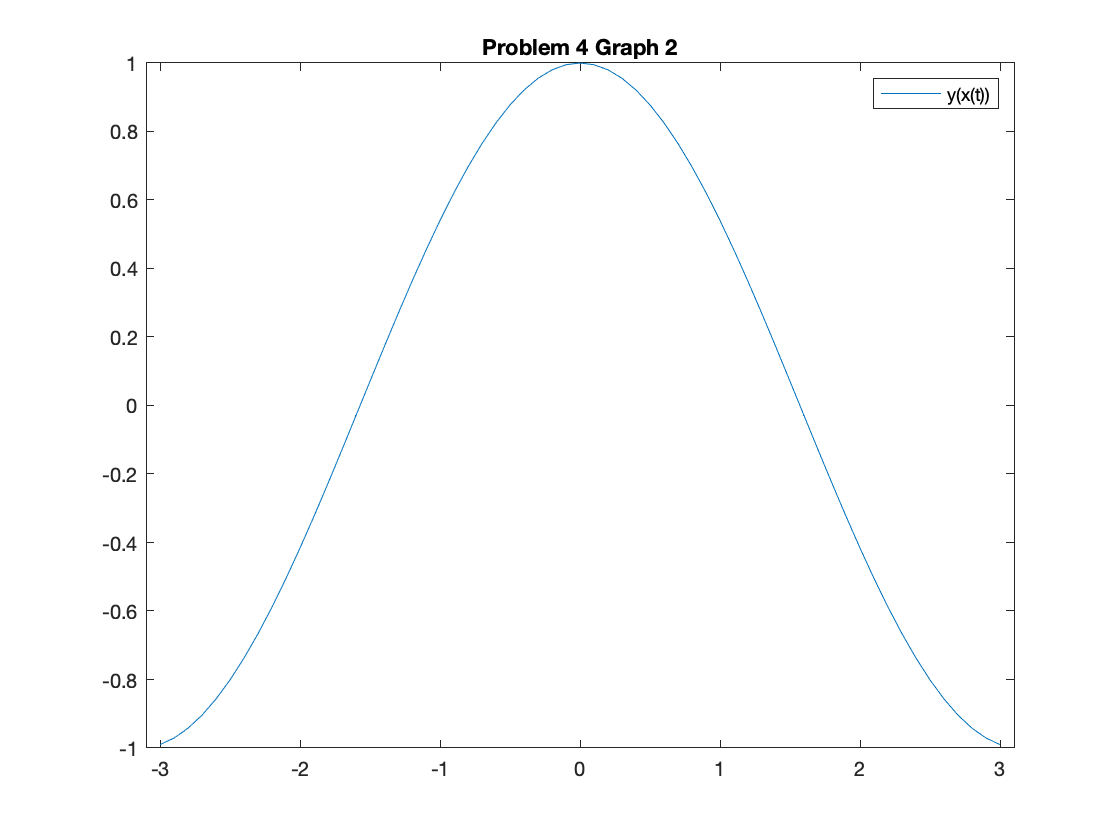


plot(t,y);
legend('y(x(t))')
xlim([-3.1 3.1]);
title('Problem 4 Graph 2')

Q6

clear all
clc

n = -3:.1:3;
%we define x1(t) and x2(t) to be functions that are n and 2*n
%we define a1 and a1 to be 1
%y[n] = n^2 * x[n]
a1 = 1; a2 =1;
x1 = n; x2 =2.*n;
y1 = n.^2 .* (a1.*x1 + a2.*x2);
y2 = a1 .* n.^2 .* x1 + a1 .* n.^2 .* x2;
all(y1==y2)

ans = logical
   0


%not linear



Q7

clear all
clc

t = -3:.1:3;
x1_t = t; x2_t = zeros(size(x1_t));
x1_tminus = t-1; x2_tminus = zeros(size(x1_t));
a1 = 1; a2 = 1;

y1 = (a1 .* x1_t) - x1_tminus;
y2 = a1.*(x1_t-x1_tminus);
all(y1==y2)

ans = logical
   1


%linear

Q9

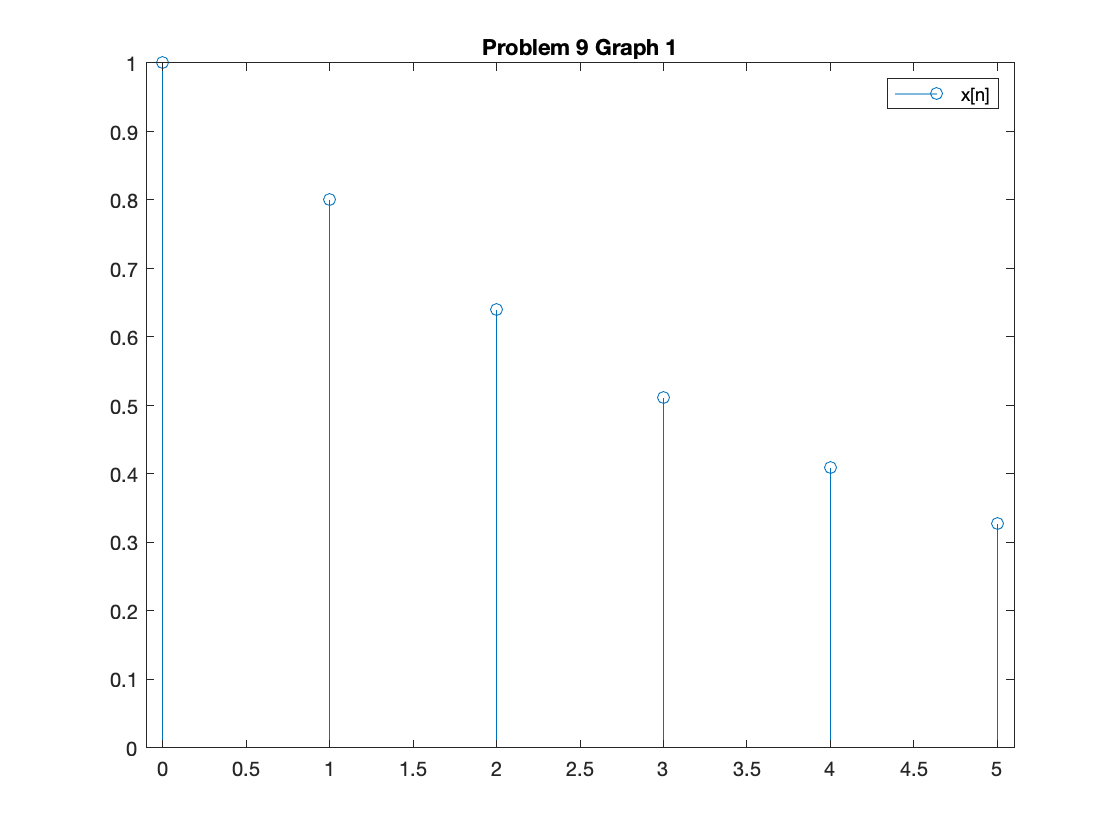

clear all
clc

n = 0:5;
x1 = 0.8.^n;
x2 = 0.8.^(5*n);

y1 = 5 * x1;
y2 = n .* x1;
y3 = x2;


stem(n,x1);
legend('x[n]')
xlim([-0.1 5.1]);
title('Problem 9 Graph 1')

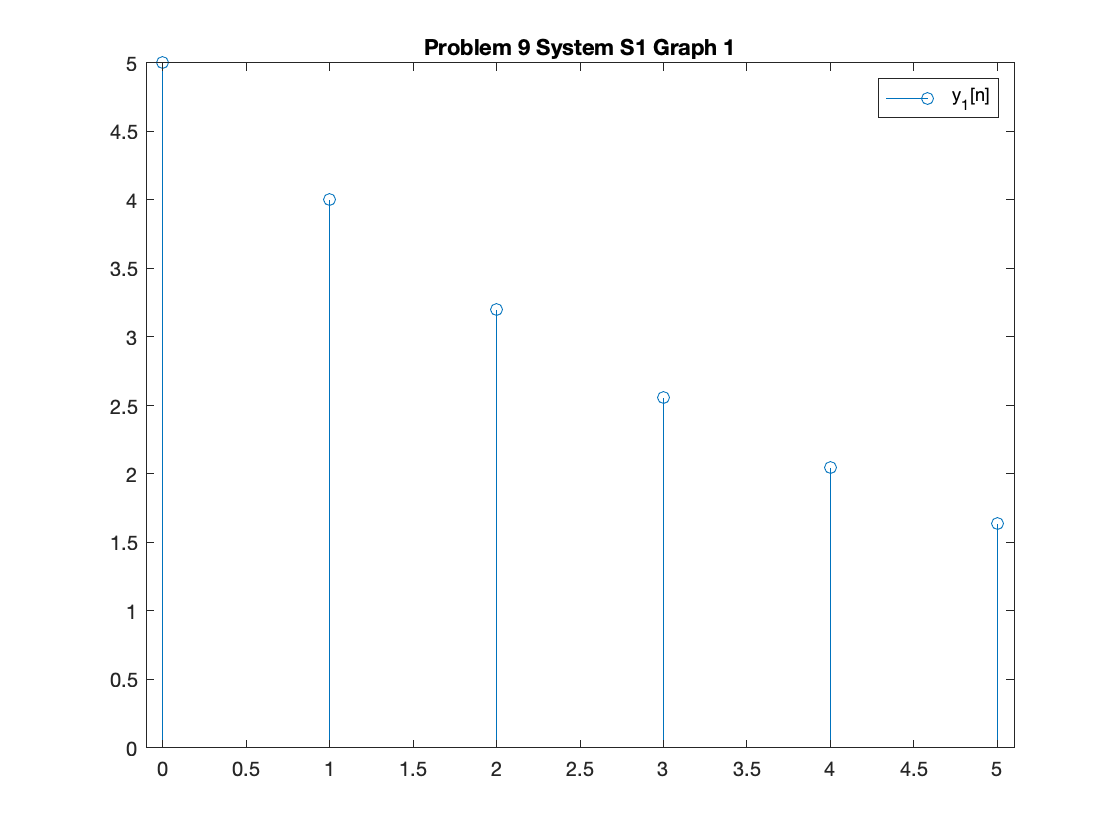


stem(n,y1);
legend('y_1[n]')
xlim([-0.1 5.1]);
title('Problem 9 System S1 Graph 1')

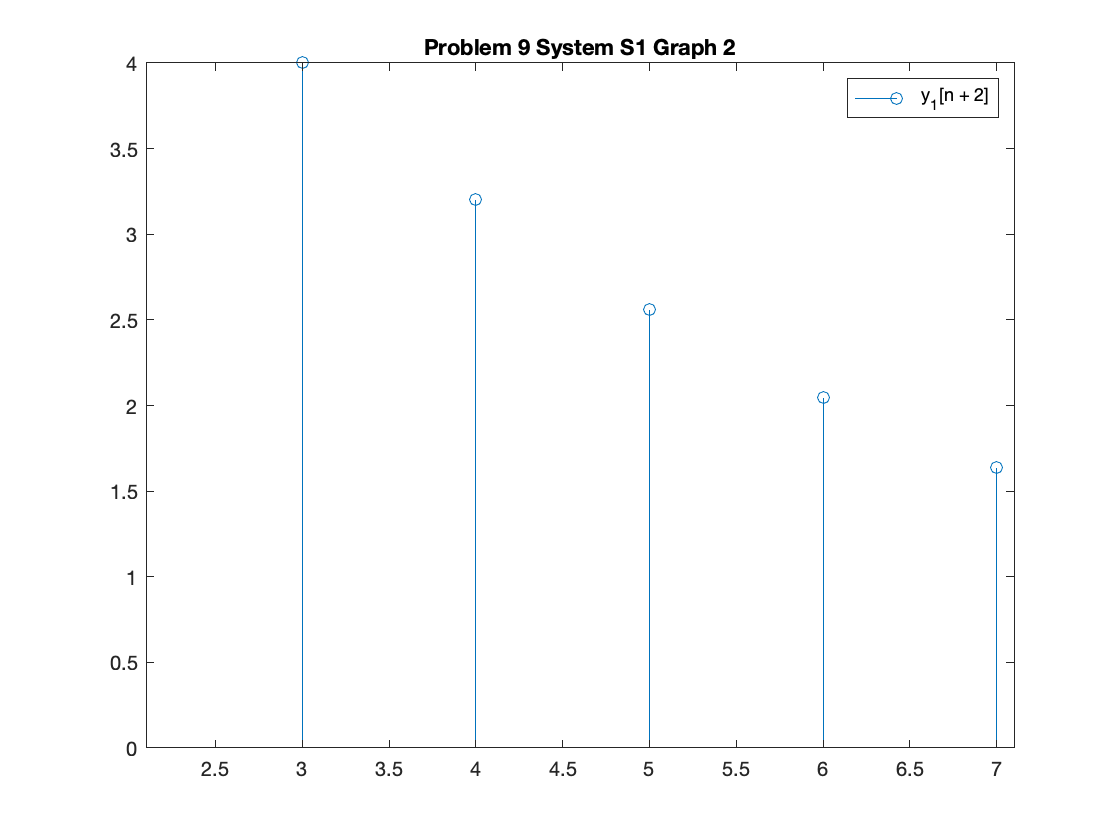


stem(n+2,y1);
legend('y_1[n + 2]')
xlim([2.1 7.1]);
title('Problem 9 System S1 Graph 2')

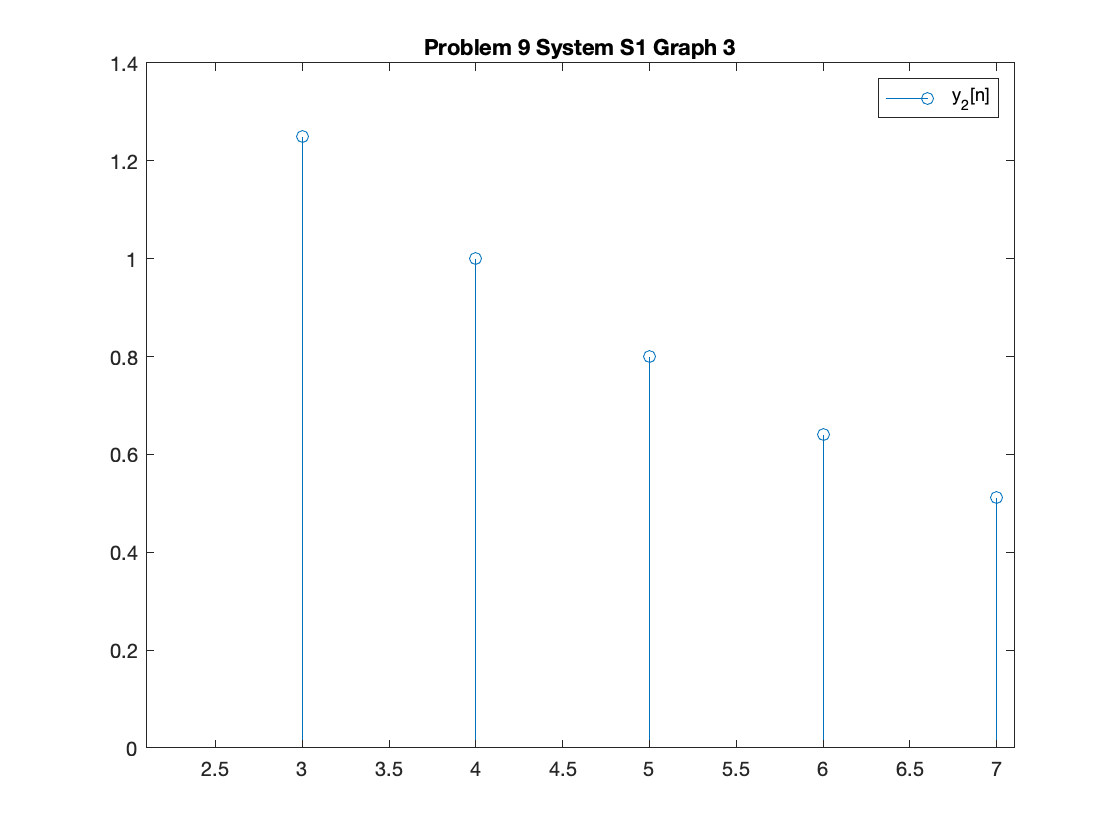


n2 = 2:7;
y12 = 0.8.^(n - 2);

stem(n2, y12);
legend('y_2[n] ')
xlim([2.1 7.1]);
title('Problem 9 System S1 Graph 3')

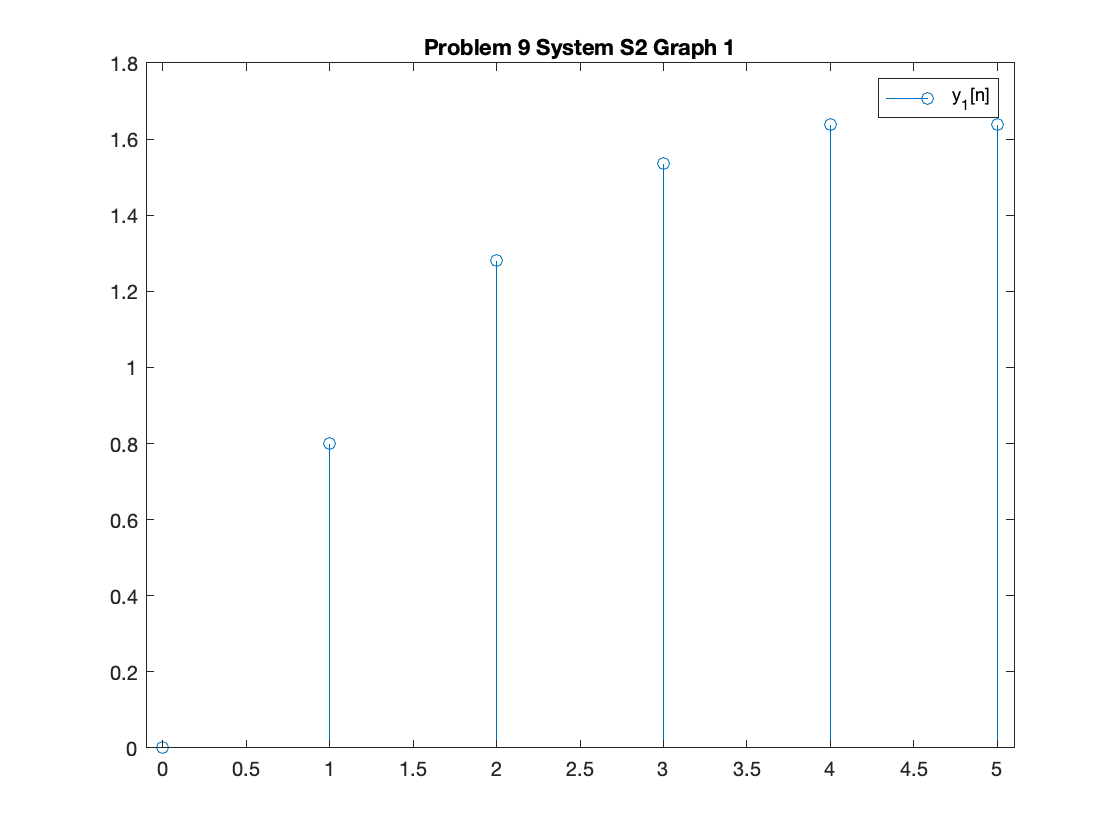




stem(n,y2);
legend('y_1[n]')
xlim([-0.1 5.1]);
title('Problem 9 System S2 Graph 1')

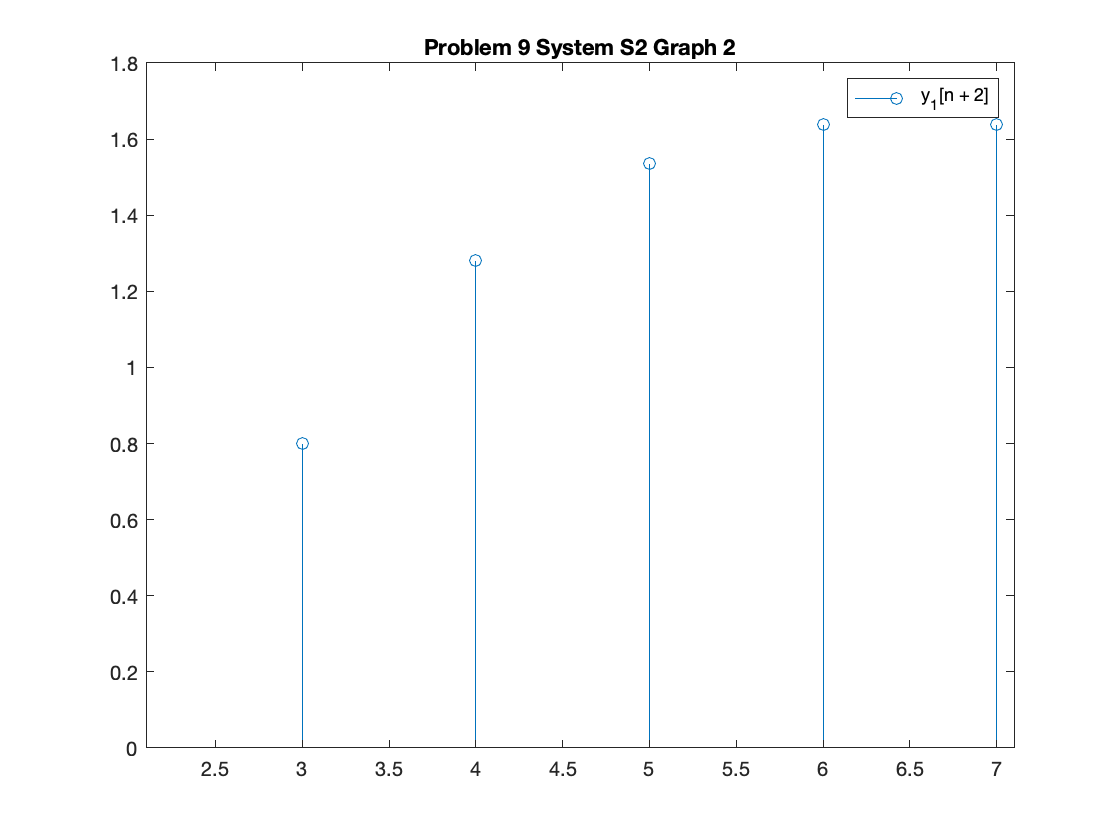


stem(n+2,y2);
legend('y_1[n + 2]')
xlim([2.1 7.1]);
title('Problem 9 System S2 Graph 2')

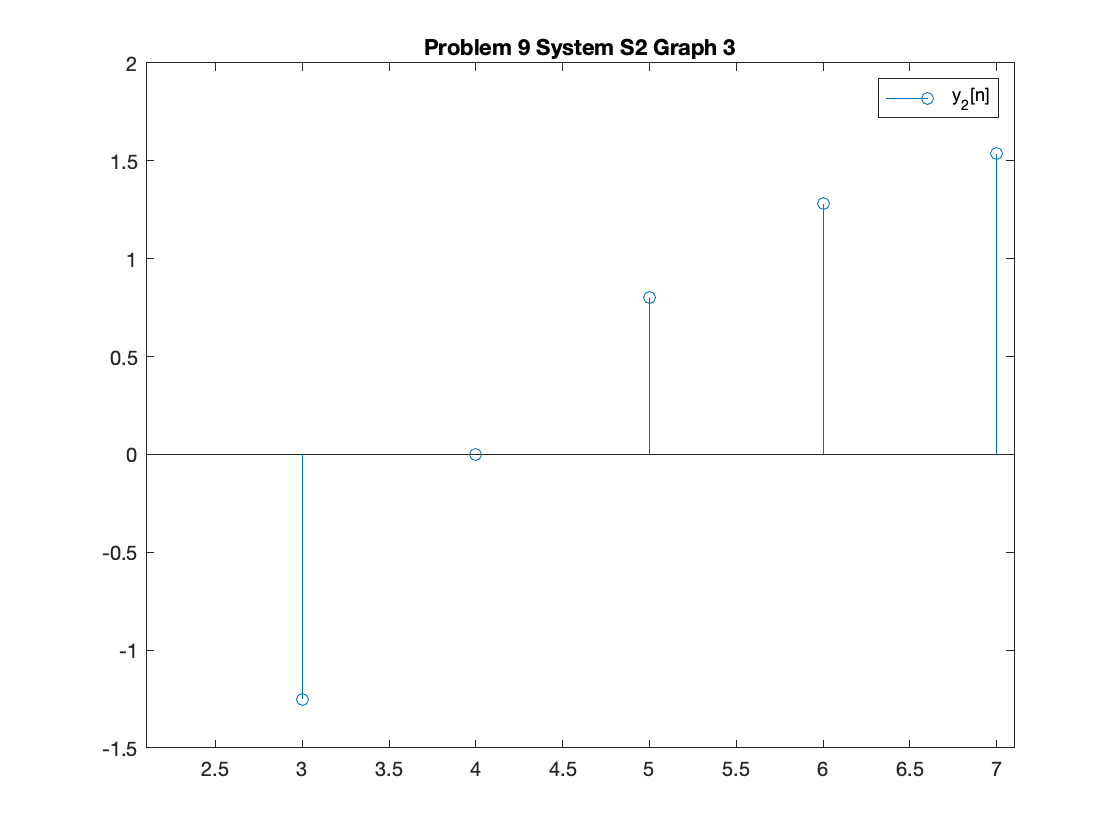


y22 = (n - 2) .* 0.8.^(n - 2);

stem(n2, y22);
legend('y_2[n] ')
xlim([2.1 7.1]);
title('Problem 9 System S2 Graph 3')

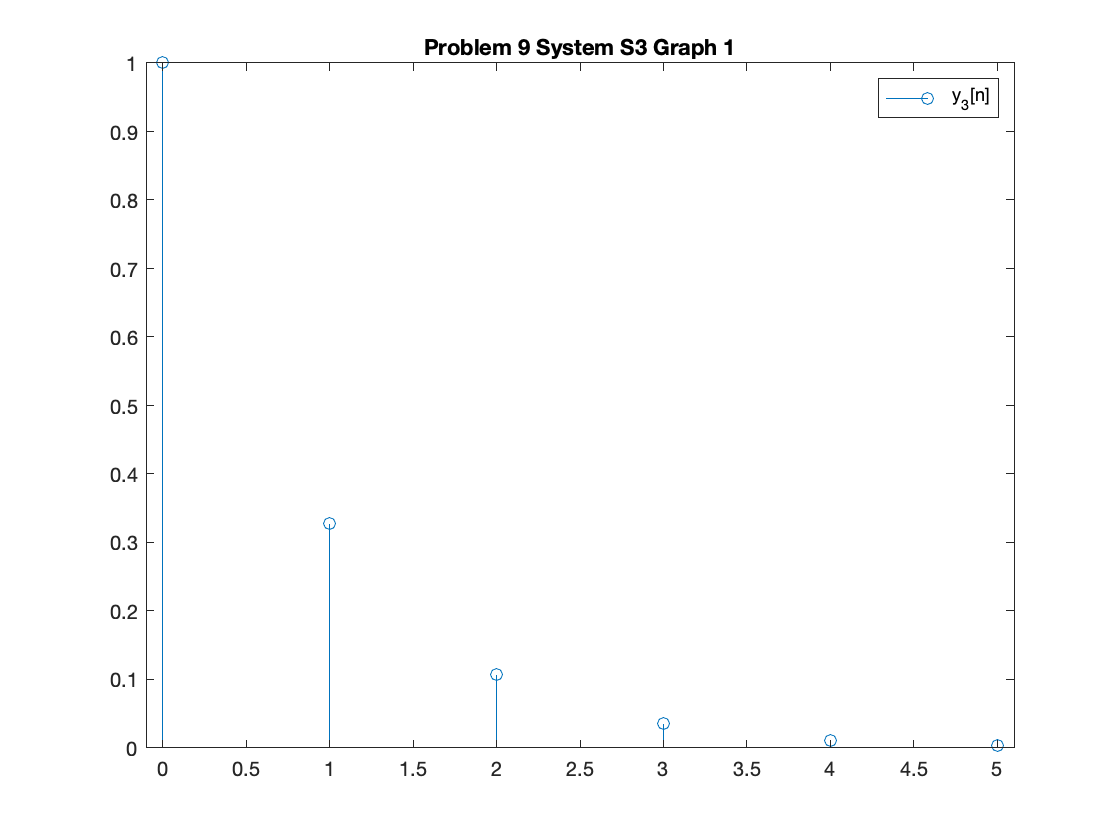




stem(n,y3);
legend('y_3[n]')
xlim([-0.1 5.1]);
title('Problem 9 System S3 Graph 1')

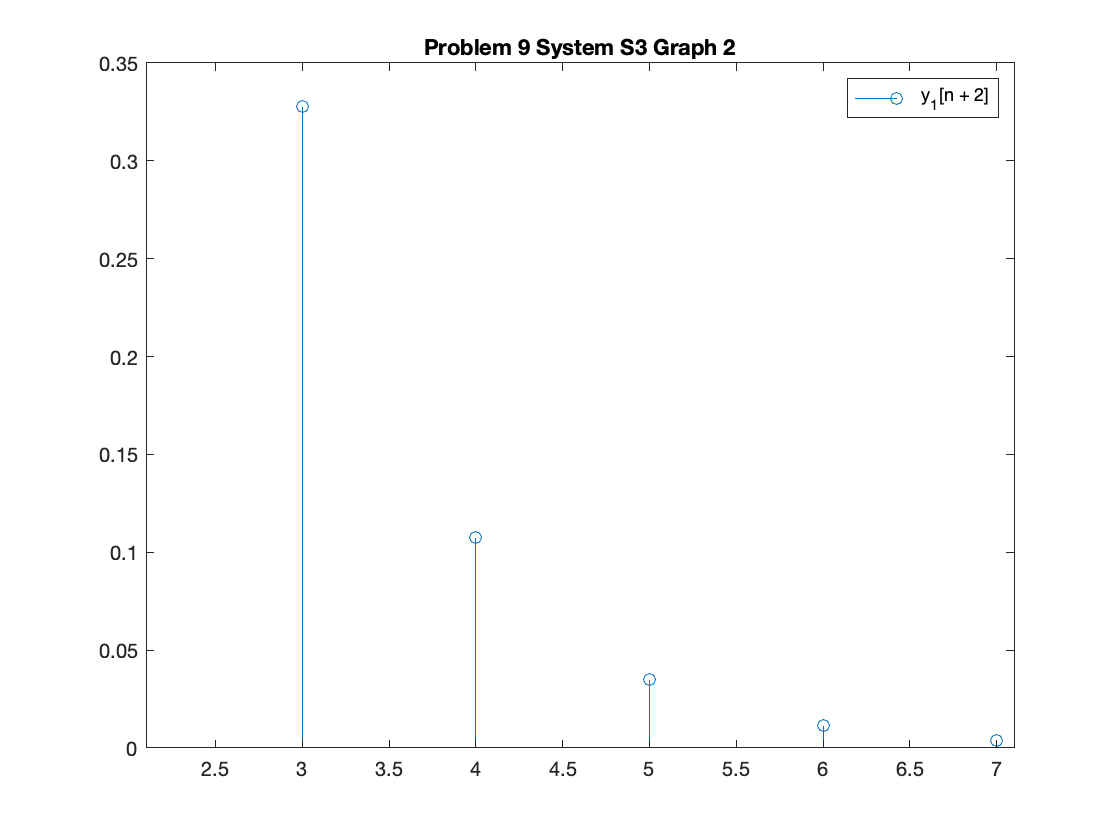


stem(n+2,y3);
legend('y_1[n + 2]')
xlim([2.1 7.1]);
title('Problem 9 System S3 Graph 2')

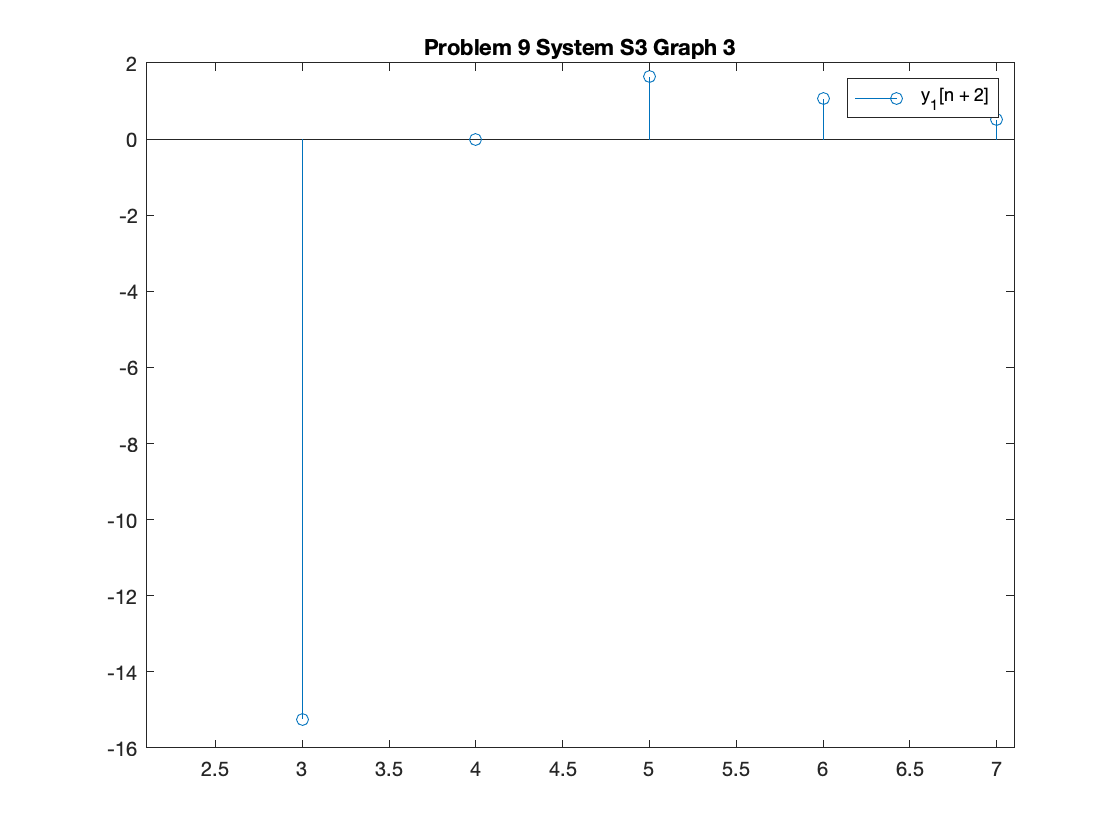


y23 = 5 * (n - 2) .* 0.8.^(5 * (n - 2));

stem(n2,y23);
legend('y_1[n + 2]')
xlim([2.1 7.1]);
title('Problem 9 System S3 Graph 3')

Q10

clear all
clc

t = -3:.1:3;
a1 = 1; a2 = 1;
x1 = t; x2 = 2.*t;
y1 = 3.*(x1 + x1) + 2.*cos(pi/3 .* (x1+x2));
y2 = 3.*x1 + 3.*x2 + 2.*(cos(pi/3 .* x1) + cos(pi/3 .* x2));
all(y1==y2) 

ans = logical
   0


% not linear

t_shift = t + 6;
x1_shifted = t_shift;
y1_shifted = 3.*x1_shifted + cos(pi/3 .* x1_shifted);
all(y1==y1_shifted)

ans = logical
   0


% shift variant

Q12

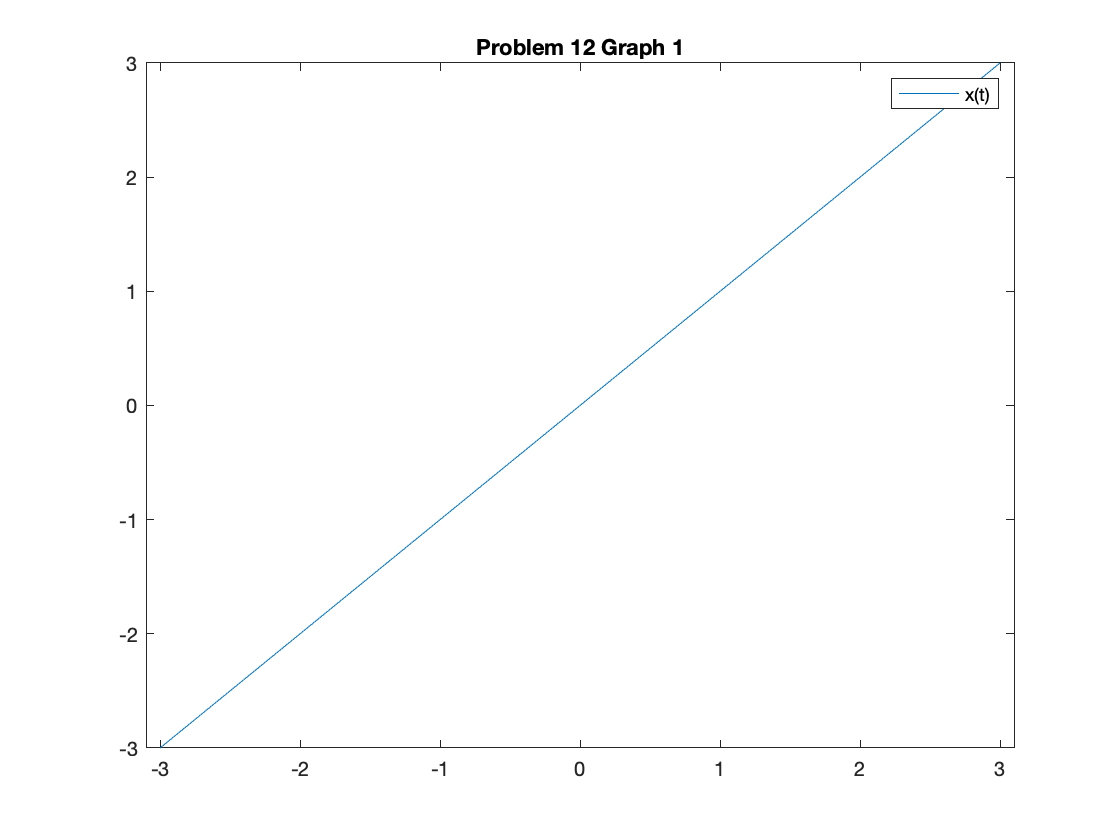

clear all
clc

t = -3:0.1:3;
x = t;
negx = -1*t;
y1 = cos(x);
y1neg = cos(negx);


plot(t,x);
legend('x(t)')
xlim([-3.1 3.1]);
title('Problem 12 Graph 1')

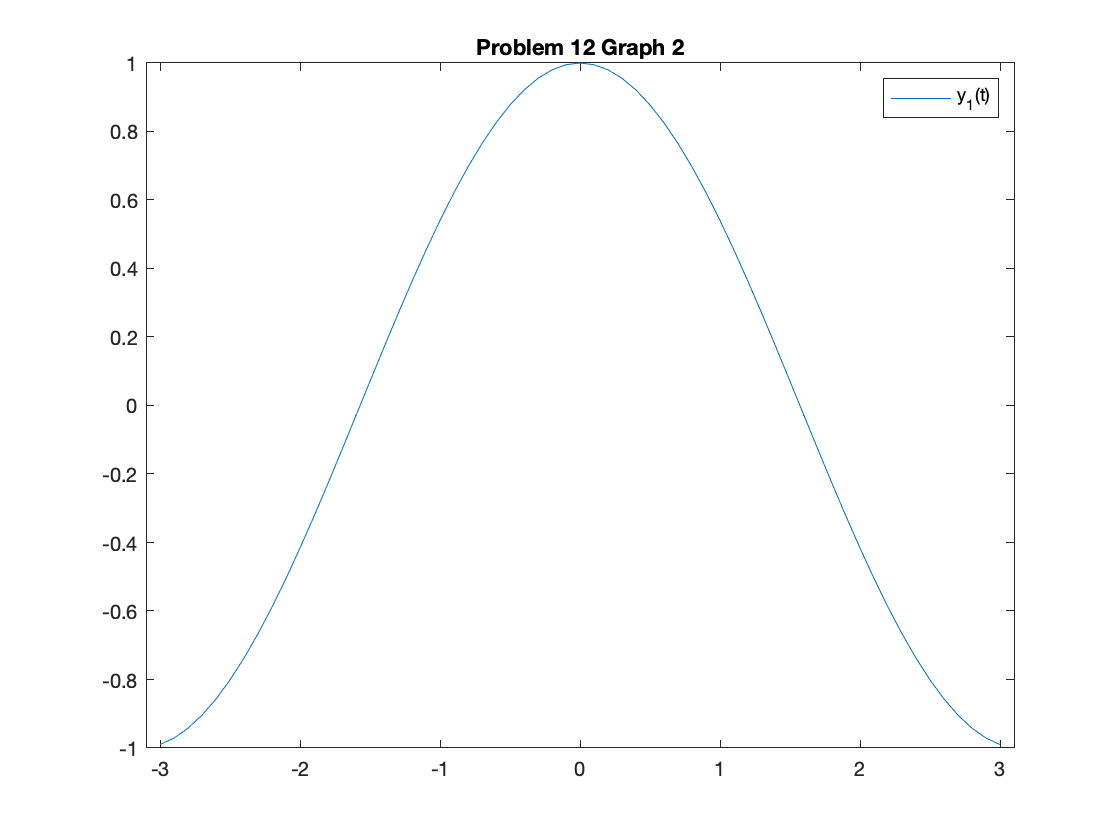


plot(t,y1);
legend('y_1(t)')
xlim([-3.1 3.1]);
title('Problem 12 Graph 2')

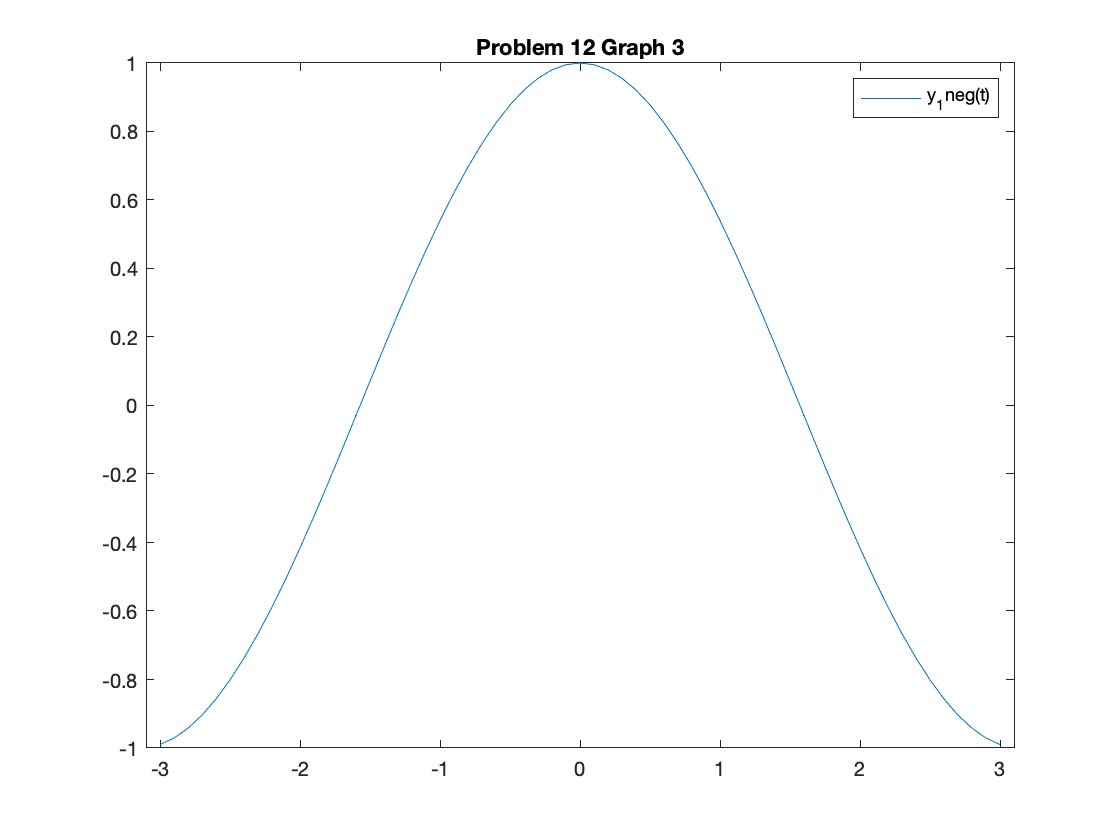


plot(t,y1neg);
legend('y_1neg(t)')
xlim([-3.1 3.1]);
title('Problem 12 Graph 3')



if(y1 == y1neg)
    fprintf("Y1 is invertable")
else fprintf("Y1 is not invertable")
end

Y1 is invertable

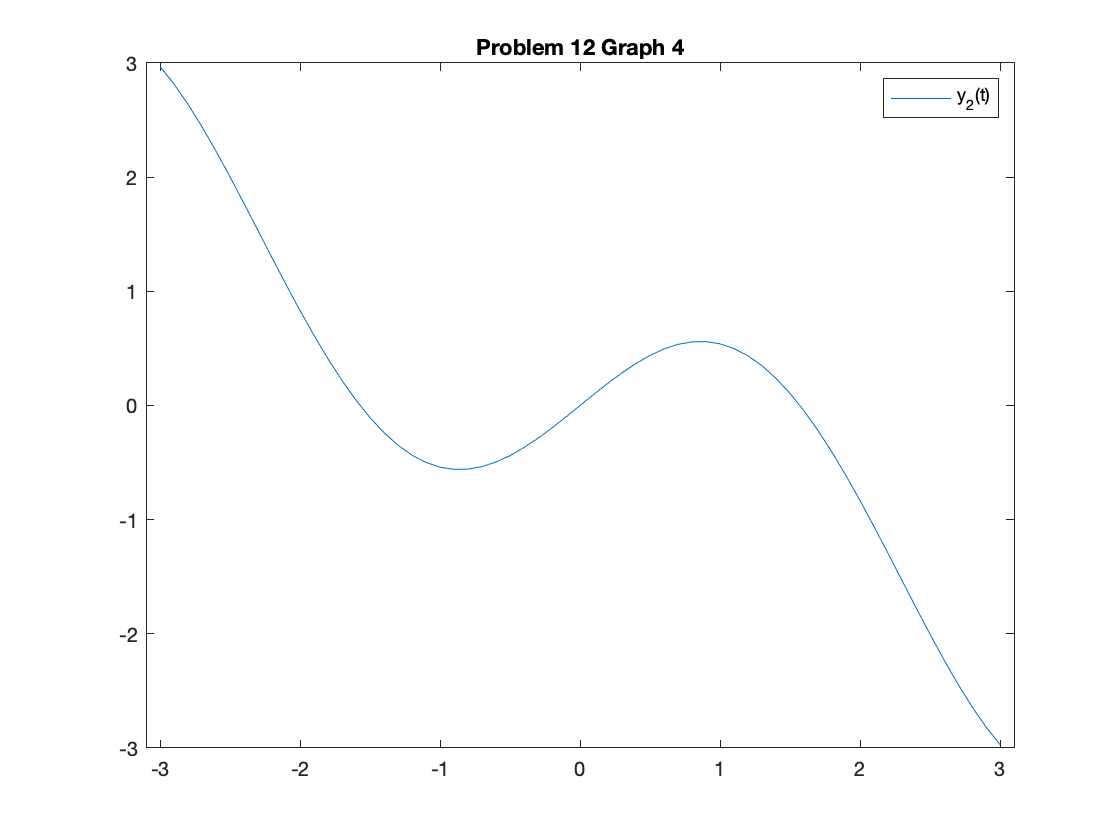


y2 = x .* cos(t);
y2neg = negx .* cos(t);

plot(t,y2);
legend('y_2(t)')
xlim([-3.1 3.1]);
title('Problem 12 Graph 4')

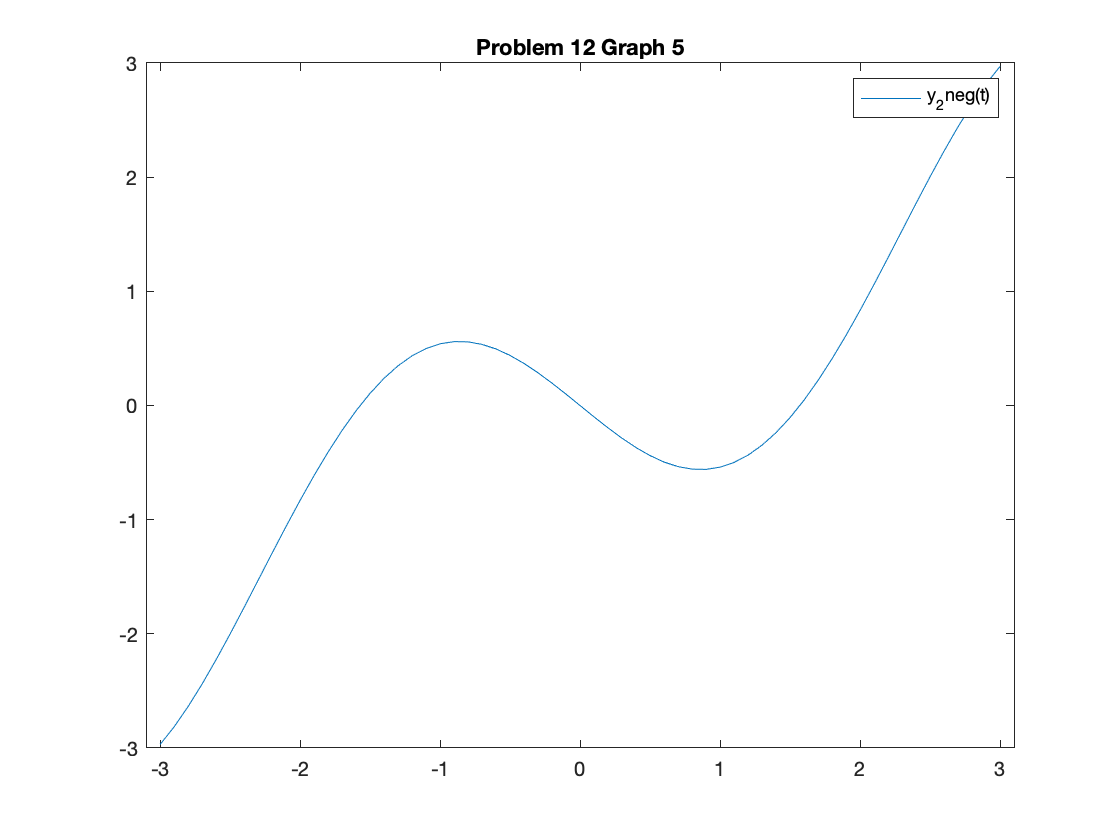


plot(t,y2neg);
legend('y_2neg(t)')
xlim([-3.1 3.1]);
title('Problem 12 Graph 5')


if(y2 == y2neg)
    fprintf("Y2 is invertable")
else fprintf("Y2 is not invertable")
end

Y2 is not invertable

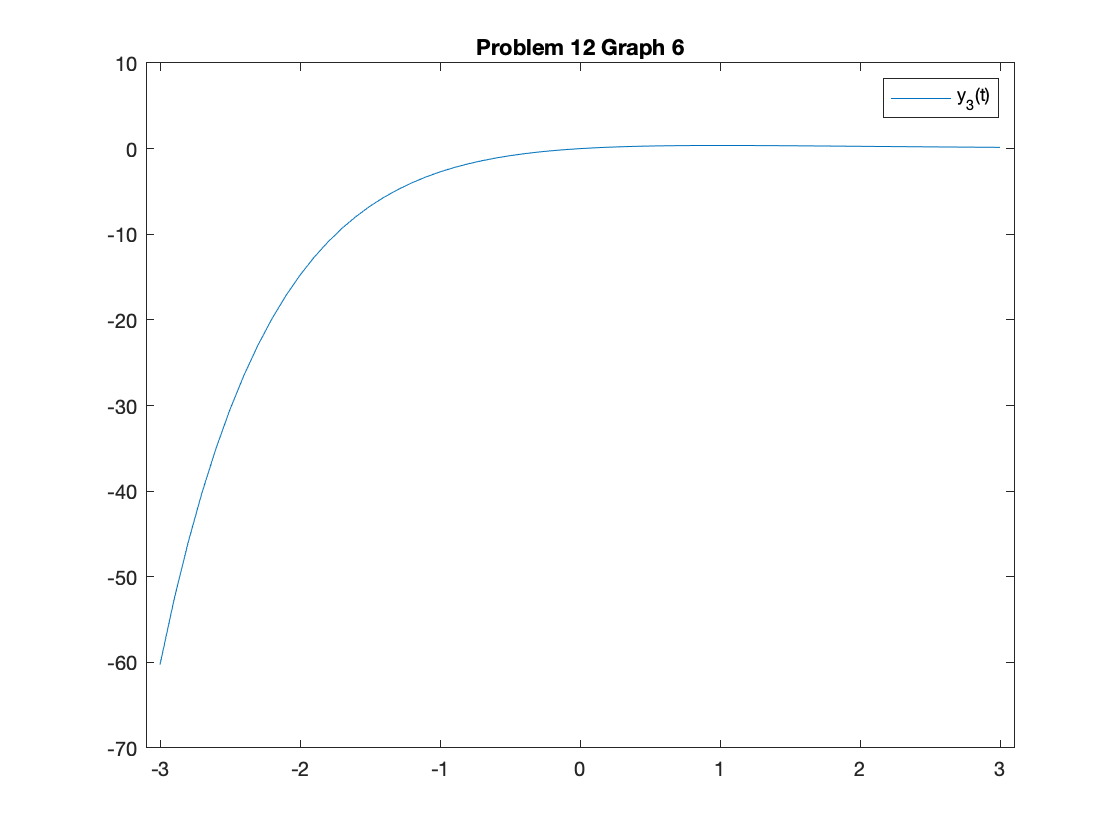


y3 = x .* exp(-t);
y3neg = negx .* exp(-t);

plot(t,y3);
legend('y_3(t)')
xlim([-3.1 3.1]);
title('Problem 12 Graph 6')

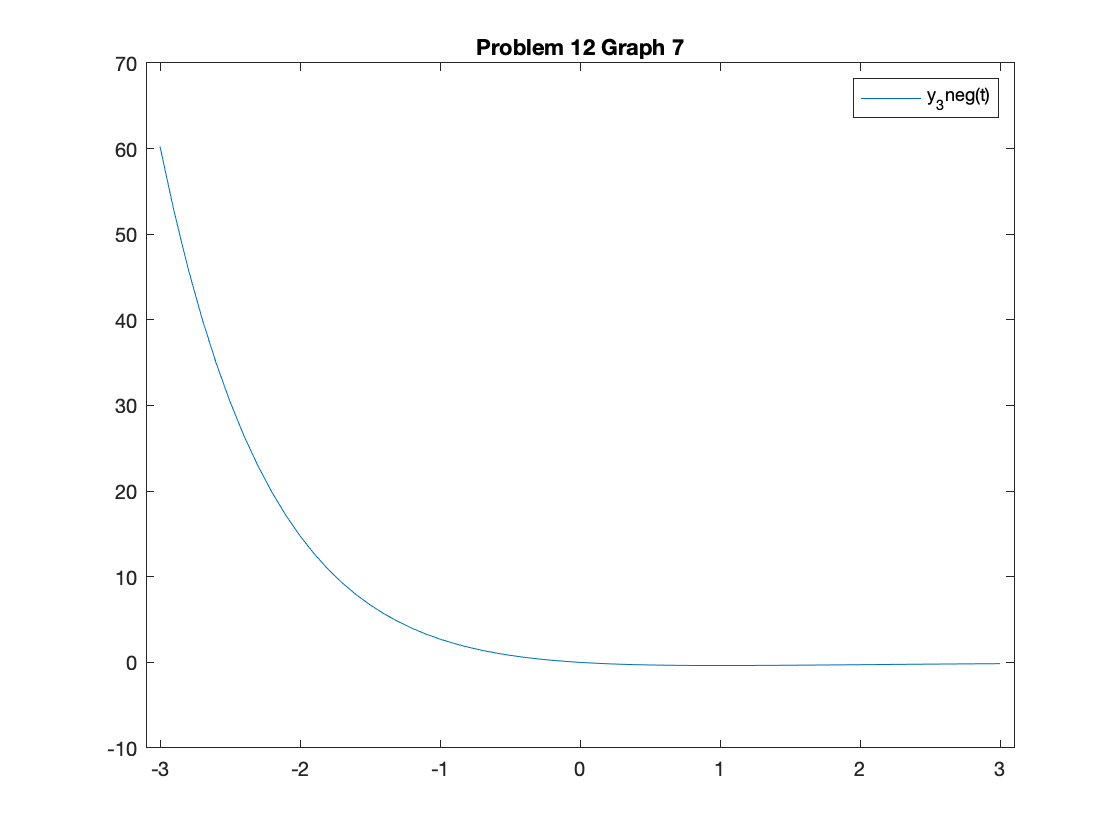


plot(t,y3neg);
legend('y_3neg(t)')
xlim([-3.1 3.1]);
title('Problem 12 Graph 7')


if(y3 == y3neg)
    fprintf("Y3 is invertable")
else fprintf("Y3 is not invertable")
end

Y3 is not invertable

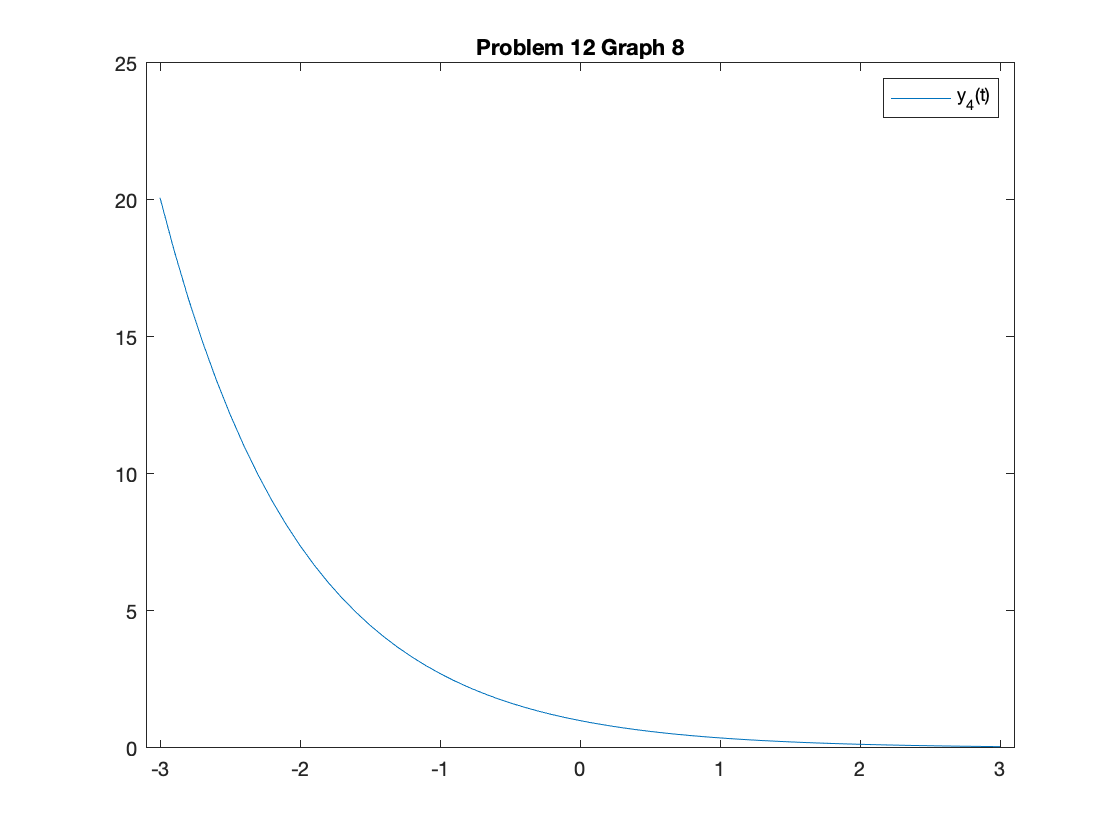



y4 =  exp(-x);
y4neg = exp(-negx);

plot(t,y4);
legend('y_4(t)')
xlim([-3.1 3.1]);
title('Problem 12 Graph 8')

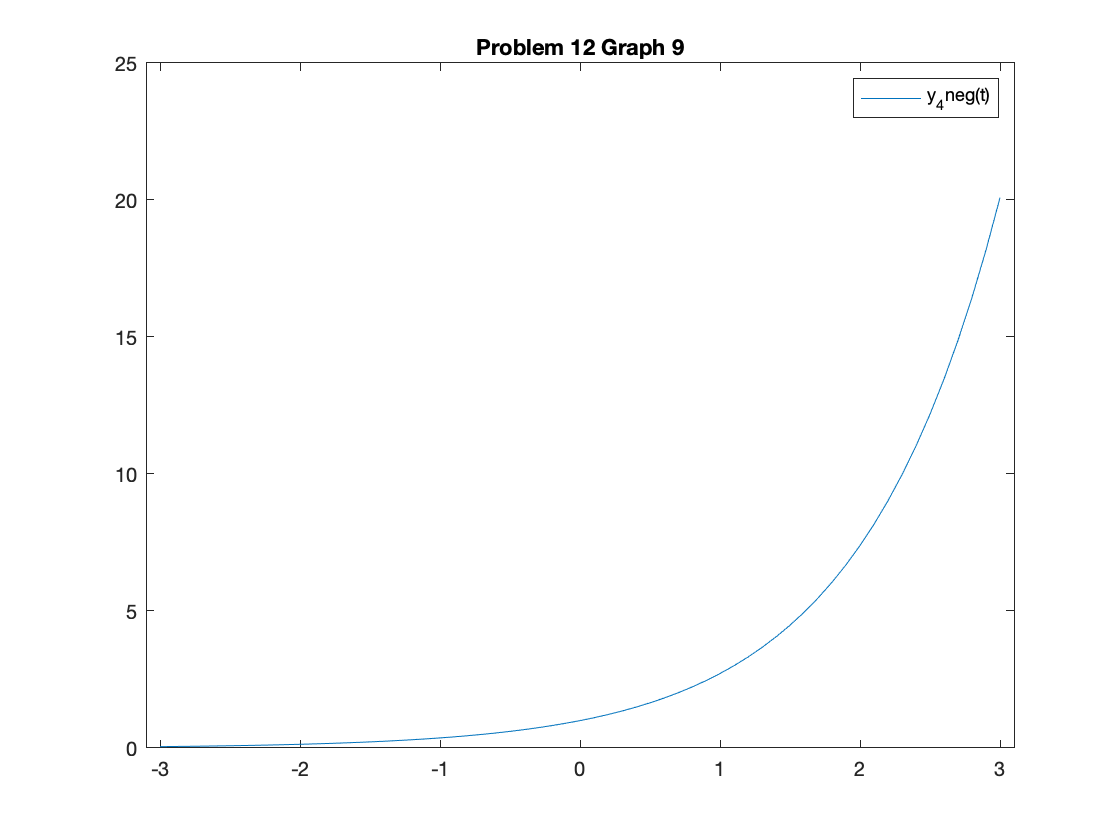


plot(t,y4neg);
legend('y_4neg(t)')
xlim([-3.1 3.1]);
title('Problem 12 Graph 9')


if(y4 == y4neg)
    fprintf("Y4 is invertable")
else fprintf("Y4 is not invertable")
end

Y4 is not invertable